# load file and generate angle

% load img

[wimg6 dname] = uigetfile('M:\Bergles Lab Data\Projects\In vivo imaging\*.tif');
[wimg24 dname2] = uigetfile('M:\Bergles Lab Data\Projects\In vivo imaging\*.tif');
img6 = loadTif([dname wimg6],16);
img24 = loadTif([dname2 wimg24],16);

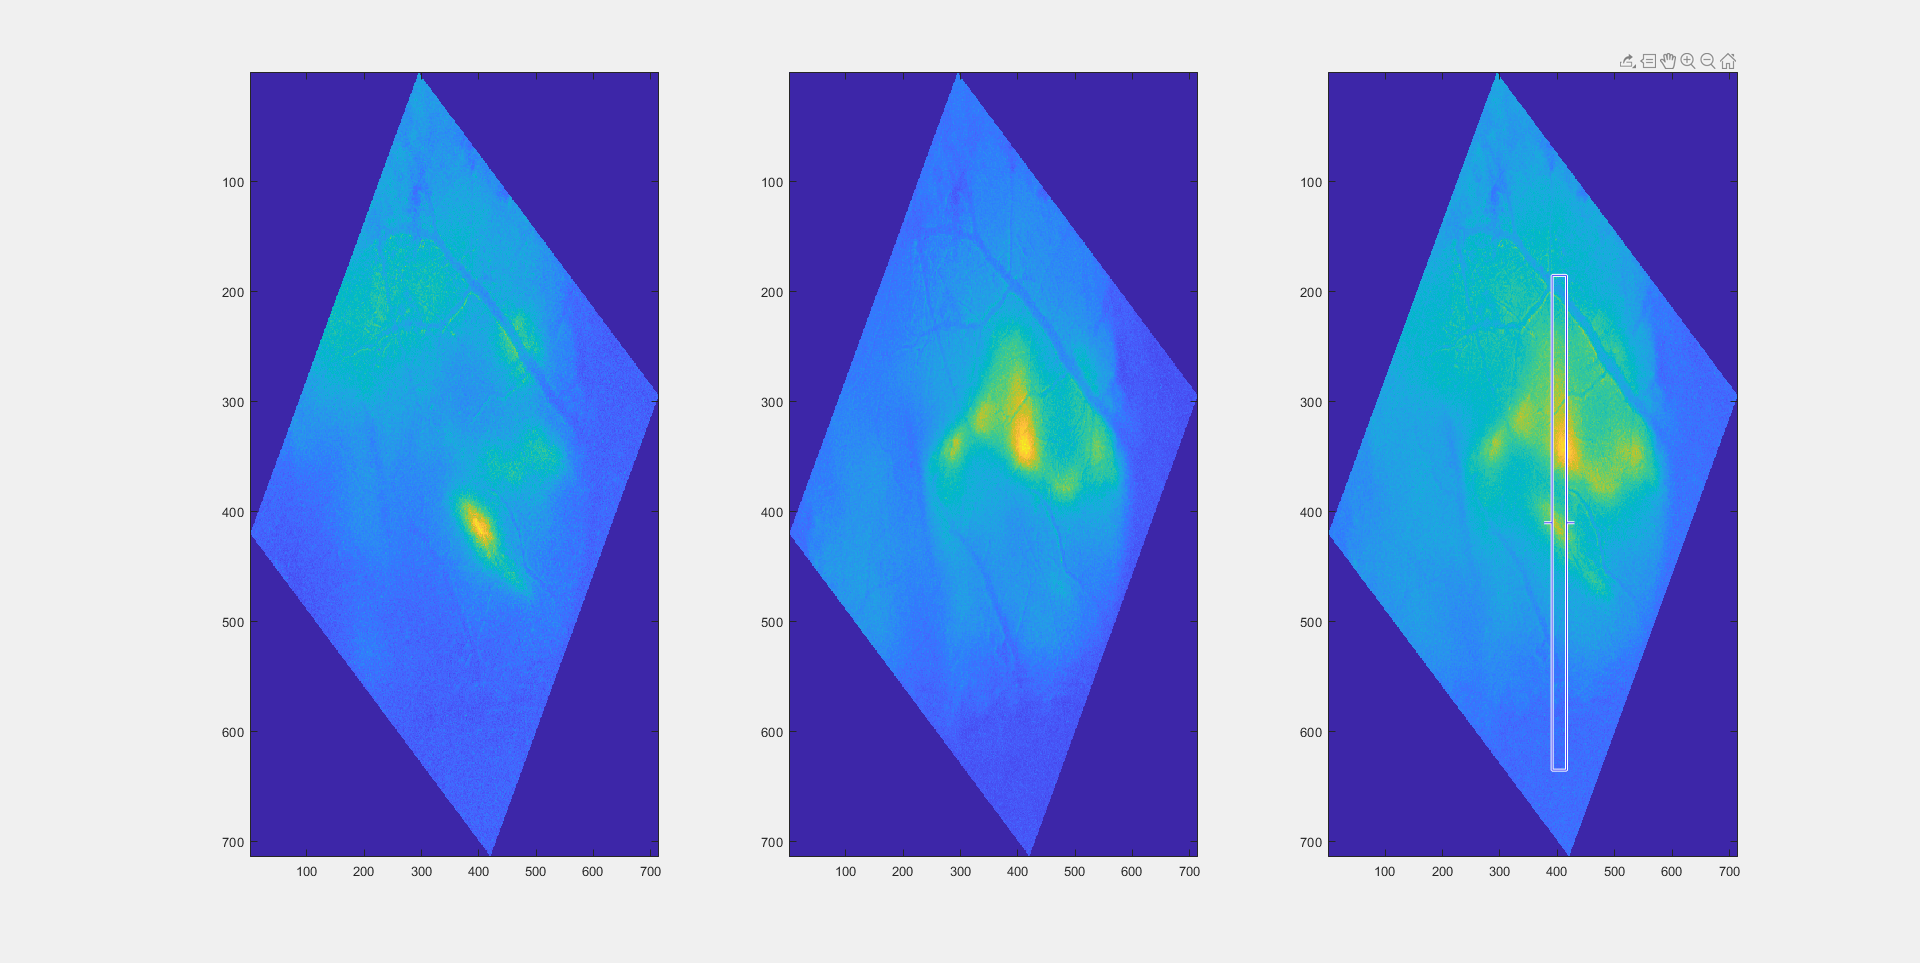


x1 = input('Rotate? (degrees)');
maxProjMean = (img6+img24)./2;
rotateMaxProj1 = imrotate(img6, x1);
rotateMaxProj2 = imrotate(img24, x1);
rotateMaxProjMean = imrotate(maxProjMean, x1);
figure
subplot(1,3,1)
h_im = imagesc(rotateMaxProj1);
subplot(1,3,2)
h_im = imagesc(rotateMaxProj2);
subplot(1,3,3)
h_im = imagesc(rotateMaxProjMean);
%caxis([-0.1 0.4]);
AC1 = imrect(gca,[100,100,25,450]);
setResizable(AC1,0);
wait(AC1);

pos = getPosition(AC1);
pos = int16(round(pos));


defaultDir = 'F:\Calvin\tmem16a\AC widefield sound\427_3 flfl\';
save([defaultDir '427_3_20dBprofile6khz.mat'],'x1')



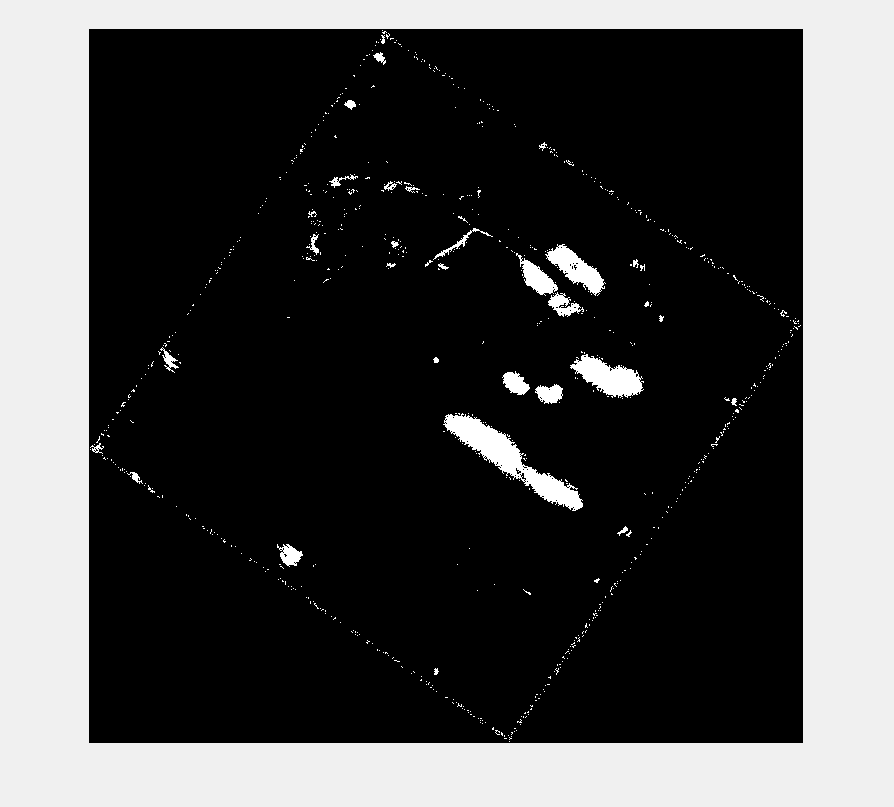

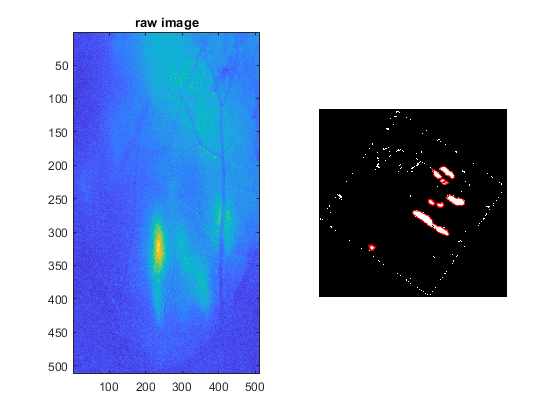

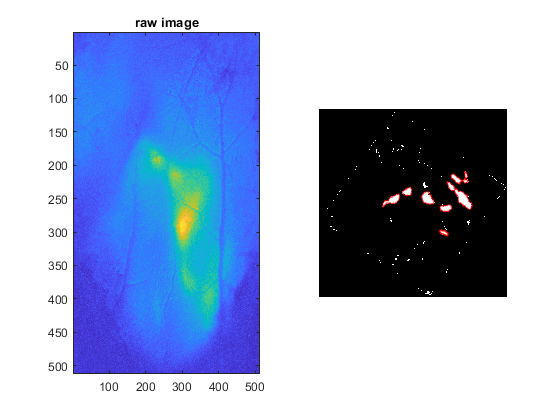

addpath('441_1 flfl','500_2 flfl','427_1 flfl','427_3 flfl','427_2 tecta flfl','437_2 tecta flfl','443_2 tecta flfl','500_1 tecta flfl','502_3 tecta flfl')

%con1 = load('500_2_20dBprofile6khz.mat'); 
con4 = load('427_3_20dBprofile6khz.mat'); 
con4 = getACmaps(con4); %500_2

save (['427_3_20dBmapP13_0db.mat'],'con4')


figure
hold on
boundptsx = [];
boundptsy = [];
for x = 1:con1(1).numbounds3 
    hold on
    plot(con1(x).boundary3(:,2)-con1(1).centroid(1,1),con1(x).boundary3(:,1)-con1(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(con1(x).boundary3(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(x).boundary3(:,1)-con1(1).centroid(1,2))'];
end
    
for x = 1:con1(1).numbounds48 
    plot(con1(x).boundary48(:,2)-con1(1).centroid(1,1),con1(x).boundary48(:,1)-con1(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(con1(x).boundary48(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(x).boundary48(:,1)-con1(1).centroid(1,2))'];

end
for x = 1:con2(1).numbounds3 
    hold on
    plot(con2(x).boundary3(:,2)-con2(1).centroid(1,1),con2(x).boundary3(:,1)-con2(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(con2(x).boundary3(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(x).boundary3(:,1)-con2(1).centroid(1,2))'];
end
    
for x = 1:con2(1).numbounds48 
    plot(con2(x).boundary48(:,2)-con2(1).centroid(1,1),con2(x).boundary48(:,1)-con2(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(con2(x).boundary48(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(x).boundary48(:,1)-con2(1).centroid(1,2))'];

end
for x = 1:con3(1).numbounds3 
    hold on
    plot(con3(x).boundary3(:,2)-con3(1).centroid(1,1),con3(x).boundary3(:,1)-con3(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(con3(x).boundary3(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(x).boundary3(:,1)-con3(1).centroid(1,2))'];
end
    
for x = 1:con3(1).numbounds48 
    plot(con3(x).boundary48(:,2)-con3(1).centroid(1,1),con3(x).boundary48(:,1)-con3(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(con3(x).boundary48(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(x).boundary48(:,1)-con3(1).centroid(1,2))'];

end

for x = 1:con4(1).numbounds3 
    hold on
    plot(con4(x).boundary3(:,2)-con4(1).centroid(1,1),con4(x).boundary3(:,1)-con4(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(con4(x).boundary3(:,2)-con4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con4(x).boundary3(:,1)-con4(1).centroid(1,2))'];
end
    
for x = 1:con4(1).numbounds48 
    plot(con4(x).boundary48(:,2)-con4(1).centroid(1,1),con4(x).boundary48(:,1)-con4(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(con4(x).boundary48(:,2)-con4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con4(x).boundary48(:,1)-con4(1).centroid(1,2))'];

end

xlim([-300 300])
ylim([-300 300])
[k areacon] = boundary(boundptsx',boundptsy',0)

k =          569
         588
        6872
        6876
        6664
        6676
        6681
        4505
        4510
         715


areacon = 80268

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)
scale = 6.1836; % microns per pixel
areaconS = areacon*(scale)*scale/1000/1000

areaconS = 3.0692

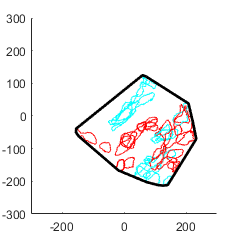

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 

figQuality(gcf,gcf,[2.5 2.5])


% cKO 
figure
hold on
boundptsx = [];
boundptsy = [];
for x = 1:cko1(1).numbounds3 
    hold on
    plot(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1),cko1(x).boundary3(:,1)-cko1(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(x).boundary3(:,1)-cko1(1).centroid(1,2))'];
end
    
for x = 1:cko1(1).numbounds48 
    plot(cko1(x).boundary48(:,2)-cko1(1).centroid(1,1),cko1(x).boundary48(:,1)-cko1(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(cko1(x).boundary48(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(x).boundary48(:,1)-cko1(1).centroid(1,2))'];

end
for x = 1:cko2(1).numbounds3 
    hold on
    plot(cko2(x).boundary3(:,2)-cko2(1).centroid(1,1),cko2(x).boundary3(:,1)-cko2(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko2(x).boundary3(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(x).boundary3(:,1)-cko2(1).centroid(1,2))'];
end
    
for x = 1:cko2(1).numbounds48 
    plot(cko2(x).boundary48(:,2)-cko2(1).centroid(1,1),cko2(x).boundary48(:,1)-cko2(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(cko2(x).boundary48(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(x).boundary48(:,1)-cko2(1).centroid(1,2))'];

end
for x = 1:cko3(1).numbounds3 
    hold on
    plot(cko3(x).boundary3(:,2)-cko3(1).centroid(1,1),cko3(x).boundary3(:,1)-cko3(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko3(x).boundary3(:,2)-cko3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko3(x).boundary3(:,1)-cko3(1).centroid(1,2))'];
end
    
for x = 1:cko3(1).numbounds48 
    plot(cko3(x).boundary48(:,2)-cko3(1).centroid(1,1),cko3(x).boundary48(:,1)-cko3(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(cko3(x).boundary48(:,2)-cko3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko3(x).boundary48(:,1)-cko3(1).centroid(1,2))'];

end
for x = 1:cko4(1).numbounds3 
    hold on
    plot(cko4(x).boundary3(:,2)-cko4(1).centroid(1,1),cko4(x).boundary3(:,1)-cko4(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko4(x).boundary3(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(x).boundary3(:,1)-cko4(1).centroid(1,2))'];
end
    
for x = 1:cko4(1).numbounds48 
    plot(cko4(x).boundary48(:,2)-cko4(1).centroid(1,1),cko4(x).boundary48(:,1)-cko4(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(cko4(x).boundary48(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(x).boundary48(:,1)-cko4(1).centroid(1,2))'];

end
for x = 1:cko5(1).numbounds3 
    hold on
    plot(cko5(x).boundary3(:,2)-cko5(1).centroid(1,1),cko5(x).boundary3(:,1)-cko5(1).centroid(1,2),'c','LineWidth', 1)
        boundptsx = [boundptsx,(cko5(x).boundary3(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(x).boundary3(:,1)-cko5(1).centroid(1,2))'];
end
    
for x = 1:cko5(1).numbounds48 
    plot(cko5(x).boundary48(:,2)-cko5(1).centroid(1,1),cko5(x).boundary48(:,1)-cko5(1).centroid(1,2),'r','LineWidth', 1)
     boundptsx = [boundptsx,(cko5(x).boundary48(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(x).boundary48(:,1)-cko5(1).centroid(1,2))'];

end
xlim([-300 300])
ylim([-300 300])
[k areacon] = boundary(boundptsx',boundptsy',0)

k =          189
        1178
        1968
        1971
        1848
        1855
        1857
        1858
        1859
        1860


areacon = 5.4329e+04

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)
scale = 6.1836; % microns per pixel
areaconS = areacon*(scale)*scale/1000/1000

areaconS = 2.0774

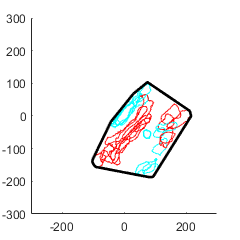

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 

figQuality(gcf,gcf,[2.5 2.5])

% A1 only
% get A1 area 6-24 kHz
%control A1 low
figure
hold on
x = 1

x = 1

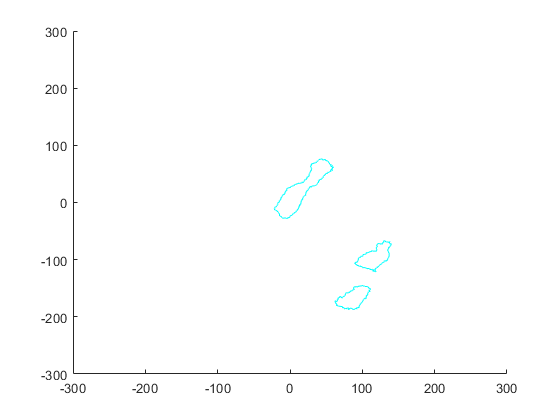

for x = 1:cko1(1).numbounds3 
    plot(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1),cko1(x).boundary3(:,1)-cko1(1).centroid(1,2),'c','LineWidth', 1)
end
xlim([-300 300])
ylim([-300 300])


cko1A1L = 1;
cko2A1L = 1;
cko3A1L = 1;
cko4A1L = 1;
cko5A1L = 1;

figure
hold on
x = 1

x = 1

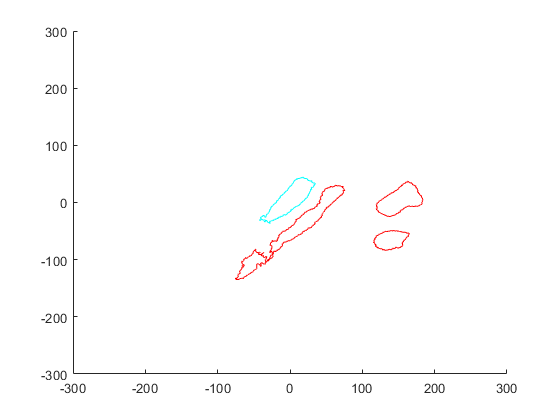

for x = 1:cko3(1).numbounds48 
    plot(cko3(x).boundary48(:,2)-cko3(1).centroid(1,1),cko3(x).boundary48(:,1)-cko3(1).centroid(1,2),'r','LineWidth', 1)
    plot(cko3(1).boundary3(:,2)-cko3(1).centroid(1,1),cko3(1).boundary3(:,1)-cko3(1).centroid(1,2),'c','LineWidth', 1)
end
xlim([-300 300])
ylim([-300 300])


cko1A1H = [1,2];
cko2A1H = [2];
cko3A1H = [1];
cko4A1H = [1];
cko5A1H = [2];

% Average A1 control
figure
A1lowcon = zeros(512,512);
bw = poly2mask([con1(1).boundary3(:,2)-con1(1).centroid(1,1)+200],[con1(1).boundary3(:,1)-con1(1).centroid(1,2)+300],512,512);
A1low1 = imfill(bw,'holes');
bw = poly2mask([con2(1).boundary3(:,2)-con2(1).centroid(1,1)+200],[con2(1).boundary3(:,1)-con2(1).centroid(1,2)+300],512,512);
A1low2 = imfill(bw,'holes');
bw = poly2mask([con3(1).boundary3(:,2)-con3(1).centroid(1,1)+200],[con3(1).boundary3(:,1)-con3(1).centroid(1,2)+300],512,512);
A1low3 = imfill(bw,'holes');
bw = poly2mask([con4(1).boundary3(:,2)-con4(1).centroid(1,1)+200],[con4(1).boundary3(:,1)-con4(1).centroid(1,2)+300],512,512);
A1low4 = imfill(bw,'holes');
A1lowcon = (A1low1+A1low2+A1low3+A1low4)./4

A1lowcon =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

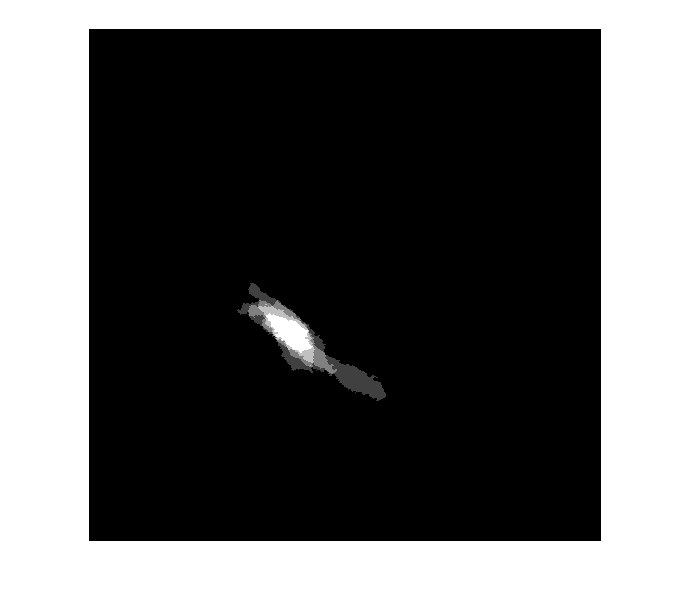

imshow(A1lowcon)

A1lowconavg = imbinarize(A1lowcon,0.3)

A1lowconavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

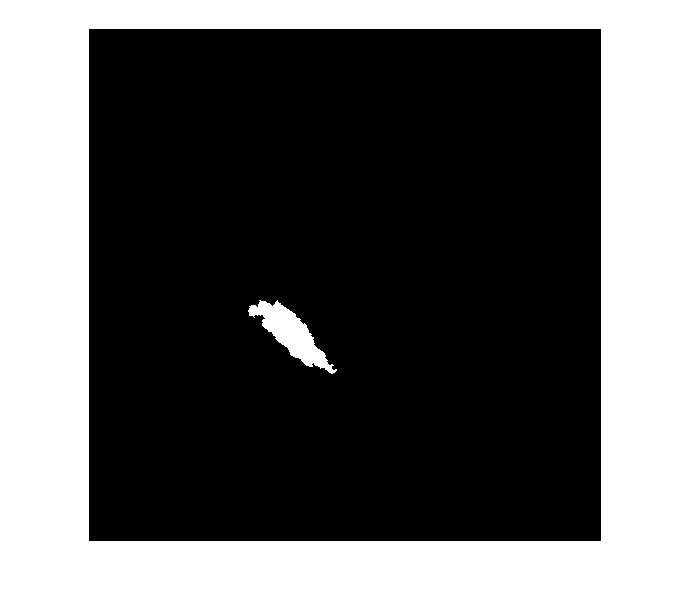

imshow(A1lowconavg)

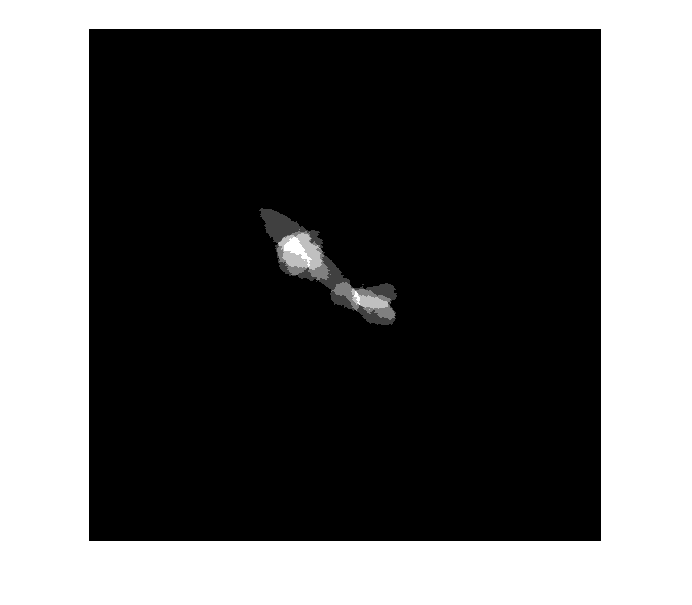

[B L] = bwboundaries(A1lowconavg, 'noholes');
Bconlow = B{1};
figure
A1highcon = zeros(512,512);
bw = poly2mask([con1(1).boundary48(:,2)-con1(1).centroid(1,1)+200],[con1(1).boundary48(:,1)-con1(1).centroid(1,2)+300],512,512);
A1high1_1 = imfill(bw,'holes');
bw = poly2mask([con1(3).boundary48(:,2)-con1(1).centroid(1,1)+200],[con1(3).boundary48(:,1)-con1(1).centroid(1,2)+300],512,512);
A1high1_2 = imfill(bw,'holes');
bw = poly2mask([con2(1).boundary48(:,2)-con2(1).centroid(1,1)+200],[con2(1).boundary48(:,1)-con2(1).centroid(1,2)+300],512,512);
A1high2_1 = imfill(bw,'holes');
% bw = poly2mask([con2(3).boundary48(:,2)-con2(1).centroid(1,1)+200],[con2(3).boundary48(:,1)-con2(1).centroid(1,2)+300],512,512);
%A1high2_2 = imfill(bw,'holes');
bw = poly2mask([con3(2).boundary48(:,2)-con3(1).centroid(1,1)+200],[con3(2).boundary48(:,1)-con3(1).centroid(1,2)+300],512,512);
A1high3_1 = imfill(bw,'holes');
bw = poly2mask([con3(3).boundary48(:,2)-con3(1).centroid(1,1)+200],[con3(3).boundary48(:,1)-con3(1).centroid(1,2)+300],512,512);
A1high3_2 = imfill(bw,'holes');
bw = poly2mask([con4(3).boundary48(:,2)-con4(1).centroid(1,1)+200],[con4(3).boundary48(:,1)-con4(1).centroid(1,2)+300],512,512);
A1high4_1 = imfill(bw,'holes');
bw = poly2mask([con4(4).boundary48(:,2)-con4(1).centroid(1,1)+200],[con4(4).boundary48(:,1)-con4(1).centroid(1,2)+300],512,512);
A1high4_2 = imfill(bw,'holes');
A1highcon = (A1high1_1+A1high1_2+A1high2_1+A1high3_1+A1high3_2+A1high4_1+A1high4_2)./4;
imshow(A1highcon)

A1highconavg = imbinarize(A1highcon,0.5)

A1highconavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

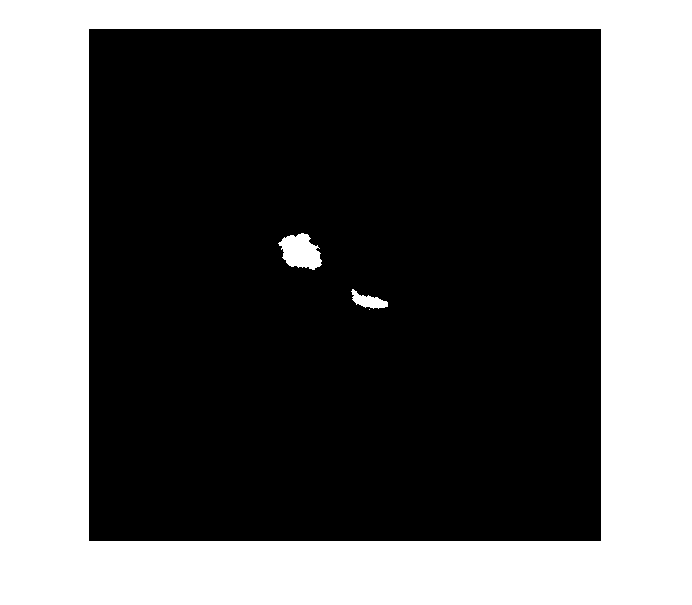

imshow(A1highconavg)

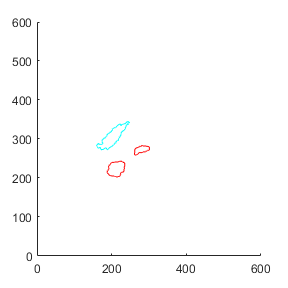

windowSize = 5;
kernel = ones(windowSize) / windowSize ^ 2;
blurryImage = conv2(single(A1highconavg), kernel, 'same');
[B1 L] = bwboundaries(blurryImage, 'noholes');
Bconhigh = struct;
for x = 1:size(B1,1)
    Bconhigh(x).bound = B1{x};    
end
figure;
plot([Bconlow(:,2)],Bconlow(:,1),'c')
hold on
for x = 1:size(B1,1)
   plot(Bconhigh(x).bound(:,2),Bconhigh(x).bound(:,1),'r') 
end
xlim([0 600])
ylim([0 600])
figQuality(gcf,gcf,[3 3])


% cKO
figure
A1lowcko = zeros(512,512);
bw = poly2mask([cko1(1).boundary3(:,2)-cko1(1).centroid(1,1)+200],[cko1(1).boundary3(:,1)-cko1(1).centroid(1,2)+300],512,512);
A1low1 = imfill(bw,'holes');
bw = poly2mask([cko2(1).boundary3(:,2)-cko2(1).centroid(1,1)+200],[cko2(1).boundary3(:,1)-cko2(1).centroid(1,2)+300],512,512);
A1low2 = imfill(bw,'holes');
bw = poly2mask([cko3(1).boundary3(:,2)-cko3(1).centroid(1,1)+200],[cko3(1).boundary3(:,1)-cko3(1).centroid(1,2)+300],512,512);
A1low3 = imfill(bw,'holes');
bw = poly2mask([cko4(1).boundary3(:,2)-cko4(1).centroid(1,1)+200],[cko4(1).boundary3(:,1)-cko4(1).centroid(1,2)+300],512,512);
A1low4 = imfill(bw,'holes');
bw = poly2mask([cko5(1).boundary3(:,2)-cko5(1).centroid(1,1)+200],[cko5(1).boundary3(:,1)-cko5(1).centroid(1,2)+300],512,512);
A1low5 = imfill(bw,'holes');
A1lowcko = (A1low1+A1low2+A1low3+A1low4+A1low5)./5

A1lowcko =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

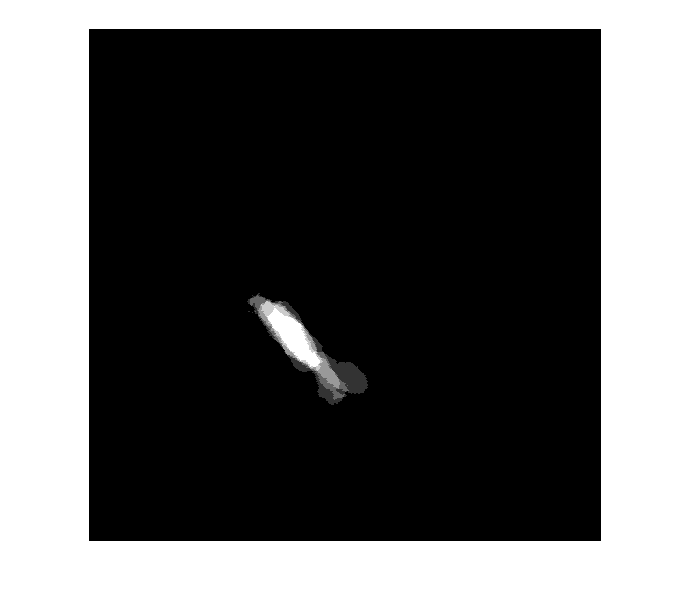

imshow(A1lowcko)

A1lowckoavg = imbinarize(A1lowcko,0.3)

A1lowckoavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

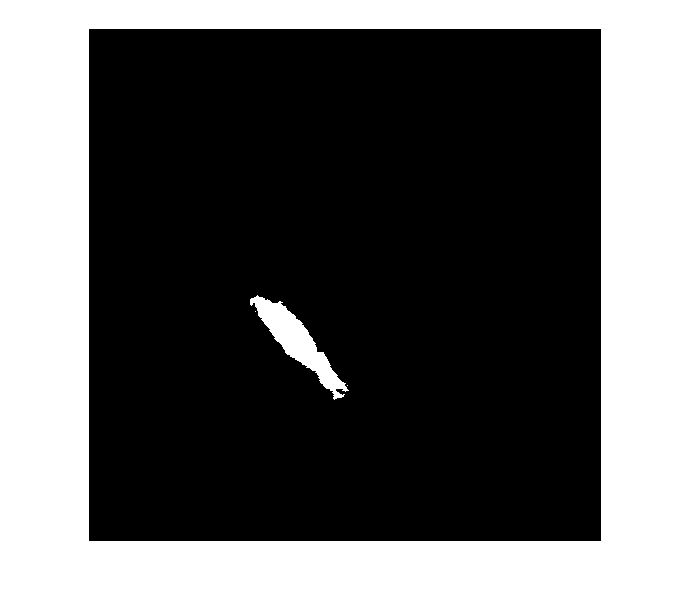

imshow(A1lowckoavg)

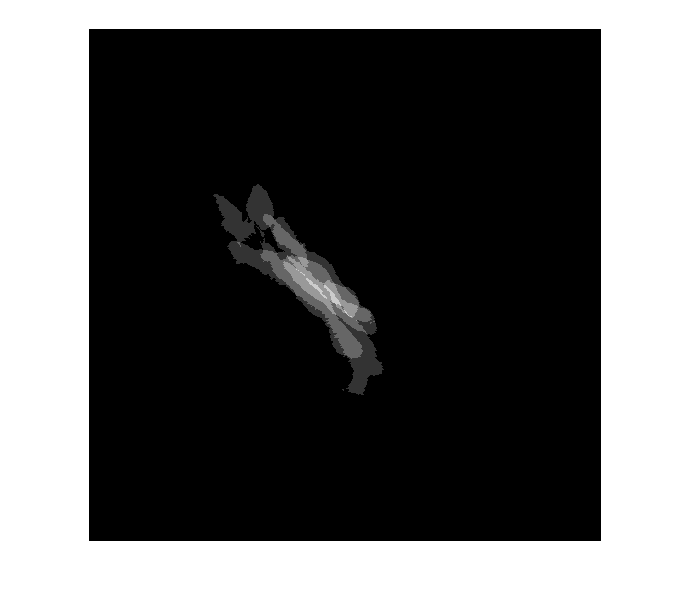

[B L] = bwboundaries(A1lowckoavg, 'noholes');
Bckolow = B{1};

figure
A1highcko = zeros(512,512);
bw = poly2mask([cko1(1).boundary48(:,2)-cko1(1).centroid(1,1)+200],[cko1(1).boundary48(:,1)-cko1(1).centroid(1,2)+300],512,512);
A1high1_1 = imfill(bw,'holes');
bw = poly2mask([cko1(2).boundary48(:,2)-cko1(1).centroid(1,1)+200],[cko1(2).boundary48(:,1)-cko1(1).centroid(1,2)+300],512,512);
A1high1_2 = imfill(bw,'holes');
bw = poly2mask([cko2(2).boundary48(:,2)-cko2(1).centroid(1,1)+200],[cko2(2).boundary48(:,1)-cko2(1).centroid(1,2)+300],512,512);
A1high2_1 = imfill(bw,'holes');
%bw = poly2mask([cko2(4).boundary48(:,2)-cko2(1).centroid(1,1)+200],[cko2(4).boundary48(:,1)-cko2(1).centroid(1,2)+300],512,512);
%A1high2_2 = imfill(bw,'holes');
bw = poly2mask([cko3(1).boundary48(:,2)-cko3(1).centroid(1,1)+200],[cko3(1).boundary48(:,1)-cko3(1).centroid(1,2)+300],512,512);
A1high3_1 = imfill(bw,'holes');
% bw = poly2mask([cko4(2).boundary48(:,2)-cko4(1).centroid(1,1)+200],[cko4(2).boundary48(:,1)-cko4(1).centroid(1,2)+300],512,512);
% A1high4_2 = imfill(bw,'holes');
bw = poly2mask([cko4(1).boundary48(:,2)-cko4(1).centroid(1,1)+200],[cko4(1).boundary48(:,1)-cko4(1).centroid(1,2)+300],512,512);
A1high4_1 = imfill(bw,'holes');
% bw = poly2mask([cko5(2).boundary48(:,2)-cko5(1).centroid(1,1)+200],[cko5(2).boundary48(:,1)-cko5(1).centroid(1,2)+300],512,512);
% A1high5_2 = imfill(bw,'holes');
bw = poly2mask([cko5(2).boundary48(:,2)-cko5(1).centroid(1,1)+200],[cko5(2).boundary48(:,1)-cko5(1).centroid(1,2)+300],512,512);
A1high5_1 = imfill(bw,'holes');
% bw = poly2mask([cko6(3).boundary48(:,2)-cko6(1).centroid(1,1)+200],[cko6(3).boundary48(:,1)-cko6(1).centroid(1,2)+300],512,512);
% A1high6_2 = imfill(bw,'holes');
A1highcko = (A1high1_1+A1high1_2+A1high2_1+A1high3_1+A1high4_1+A1high5_1)./5;
imshow(A1highcko)

A1highckoavg = imbinarize(A1highcko,0.5)

A1highckoavg = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

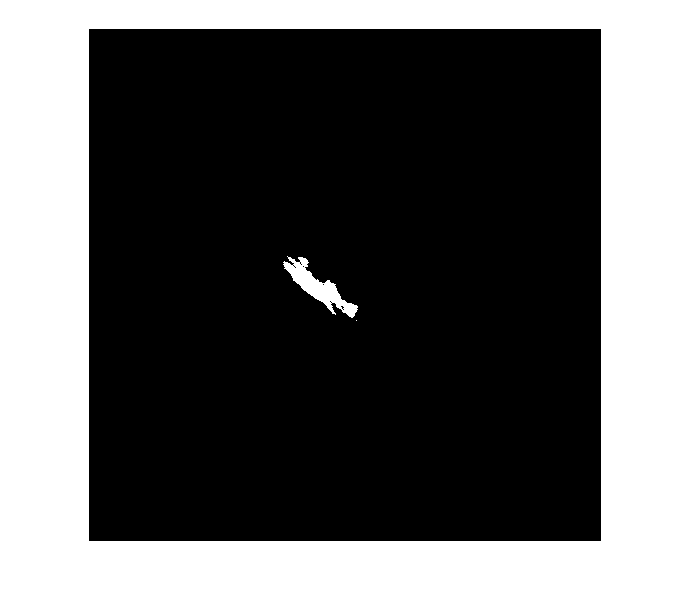

imshow(A1highckoavg); 

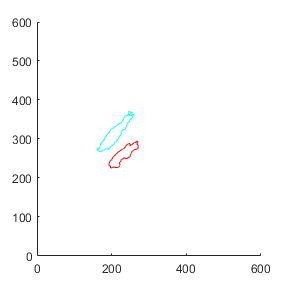

windowSize = 5;
kernel = ones(windowSize) / windowSize ^ 2;
blurryImage = conv2(single(A1highckoavg), kernel, 'same');
[B L] = bwboundaries(blurryImage, 'noholes');
Bckohigh = struct;
for x = 1:size(B,1)
    Bckohigh(x).bound = B{x};    
end
figure;
plot([Bckolow(:,2)],Bckolow(:,1),'c')
hold on
for x = 1:size(B,1)
   plot(Bckohigh(x).bound(:,2),Bckohigh(x).bound(:,1),'r') 
end
xlim([0 600])
ylim([0 600])
figQuality(gcf,gcf,[3 3])

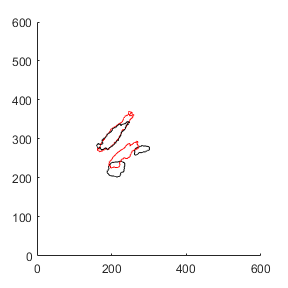

% overlay con and cKO

% combine con and cKO

figure;
plot([Bckolow(:,2)],Bckolow(:,1),'r')
hold on
plot([Bconlow(:,2)],Bconlow(:,1),'k')
for x = 1:size(B1,1)
   plot(Bconhigh(x).bound(:,2),Bconhigh(x).bound(:,1),'k') 
end

for x = 1:size(B,1)
   plot(Bckohigh(x).bound(:,2),Bckohigh(x).bound(:,1),'r') 
end
xlim([0 600])
ylim([0 600])
figQuality(gcf,gcf,[3 3])
print(gcf,'-dpdf')

% mean with bounds - combined
figure;
boundptsxcko = [];
boundptsycko = [];
boundptsxcon = [];
boundptsycon = [];
plot([smooth(Bckolow(:,2))],smooth(Bckolow(:,1)),'r')
boundptsxcko = [boundptsxcko,([Bckolow(:,2)])'];
boundptsycko = [boundptsycko,(Bckolow(:,1))'];
hold on
plot([smooth(Bconlow(:,2))],smooth(Bconlow(:,1)),'k')
boundptsxcon = [boundptsxcon,([Bconlow(:,2)])'];
boundptsycon = [boundptsycon,(Bconlow(:,1))'];
for x = 1:size(B1,1)
   plot(smooth(Bconhigh(x).bound(:,2)),smooth(Bconhigh(x).bound(:,1)),'k')
   boundptsxcon = [boundptsxcon,(Bconhigh(x).bound(:,2))'];
boundptsycon = [boundptsycon,(Bconhigh(x).bound(:,1))'];
end

for x = 1:size(B,1)
   plot(smooth(Bckohigh(x).bound(:,2)),smooth(Bckohigh(x).bound(:,1)),'r') 
   boundptsxcko = [boundptsxcko,(Bckohigh(x).bound(:,2))'];
    boundptsycko = [boundptsycko,(Bckohigh(x).bound(:,1))'];
end
xlim([0 600])
ylim([0 600]) 
[k areacKO] = boundary(boundptsxcko',boundptsycko',0)

k =      1
   316
   317
   318
   319
   320
   336
   339
   383
   413


areacKO = 9.5275e+03

[k2 areacon] = boundary(boundptsxcon',boundptsycon',0)

k2 =      1
     5
   255
   256
   260
   261
   262
   265
   268
   279


areacon = 12173

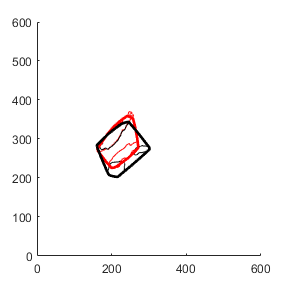

Error using matlab.ui.Figure/get
There is no TightInset property on the Figure class.

Error in figQuality (line 11)
    set(axh,'LooseInset',get(axh,'TightInset')) 


plot(smooth(boundptsxcko(k)),smooth(boundptsycko(k)),'r','LineWidth',2)
plot(smooth(boundptsxcon(k2)),smooth(boundptsycon(k2)),'k','LineWidth',2)
figQuality(gcf,gcf,[3 3])

% centroid distance + area data

scale = 6.1836; % microns per pixel
%cko1
figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
    hold on
    plot(cko1(x).boundary3(:,2)-cko1(1).centroid(1,1),cko1(x).boundary3(:,1)-cko1(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko1x cenLowcko1y] = centroid(polyshape([cko1(x).boundary3(:,2)-cko1(1).centroid(1,1)],[cko1(x).boundary3(:,1)-cko1(1).centroid(1,2)]));

    plot(cenLowcko1x,cenLowcko1y,'c*')
    boundptsx = [boundptsx,(cko1(1).boundary3(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(1).boundary3(:,1)-cko1(1).centroid(1,2))'];
    plot(cko1(y1).boundary48(:,2)-cko1(1).centroid(1,1),cko1(y1).boundary48(:,1)-cko1(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko1x cenHi1cko1y] = centroid(polyshape([cko1(y1).boundary48(:,2)-cko1(1).centroid(1,1)],[cko1(y1).boundary48(:,1)-cko1(1).centroid(1,2)]));

    plot(cenHi1cko1x,cenHi1cko1y,'r*')
    boundptsx = [boundptsx,(cko1(y1).boundary48(:,2)-cko1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko1(y1).boundary48(:,1)-cko1(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   292
   297
   300
   303
   313
   315
   316
   320
   323


areacKO = 1.0312e+04

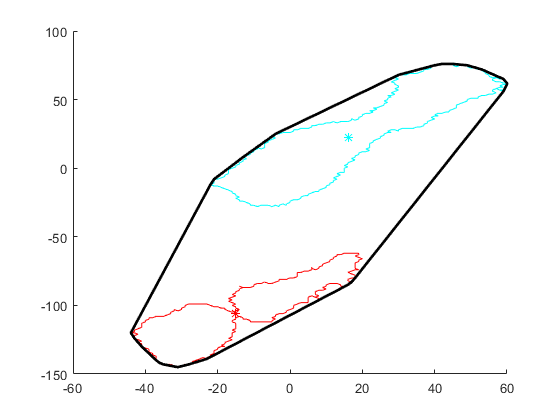

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacKO1 = areacKO*(scale)*scale/1000/1000

areacKO1 = 0.3943

cko1LHi1 = sqrt((cenHi1cko1x-cenLowcko1x)^2+(cenHi1cko1y-cenLowcko1y)^2)*scale; %meh

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
    hold on
    plot(cko2(x).boundary3(:,2)-cko2(1).centroid(1,1),cko2(x).boundary3(:,1)-cko2(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko2x cenLowcko2y] = centroid(polyshape([cko2(x).boundary3(:,2)-cko2(1).centroid(1,1)],[cko2(x).boundary3(:,1)-cko2(1).centroid(1,2)]));

    plot(cenLowcko2x,cenLowcko2y,'c*')
    boundptsx = [boundptsx,(cko2(1).boundary3(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(1).boundary3(:,1)-cko2(1).centroid(1,2))'];
    plot(cko2(y1).boundary48(:,2)-cko2(1).centroid(1,1),cko2(y1).boundary48(:,1)-cko2(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko2x cenHi1cko2y] = centroid(polyshape([cko2(y1).boundary48(:,2)-cko2(1).centroid(1,1)],[cko2(y1).boundary48(:,1)-cko2(1).centroid(1,2)]));

    plot(cenHi1cko2x,cenHi1cko2y,'r*')
    boundptsx = [boundptsx,(cko2(y1).boundary48(:,2)-cko2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko2(y1).boundary48(:,1)-cko2(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   425
   428
   429
   430
   431
   432
   433
   435
   484


areacKO = 1.2039e+04

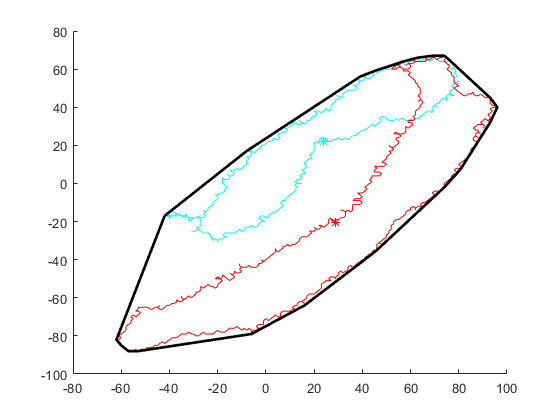

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacko2 = areacKO*(scale)*scale/1000/1000

areacko2 = 0.4603

cko2LHi1 = sqrt((cenHi1cko2x-cenLowcko2x)^2+(cenHi1cko2y-cenLowcko2y)^2)*scale; 

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
    hold on
    plot(cko3(x).boundary3(:,2)-cko3(1).centroid(1,1),cko3(x).boundary3(:,1)-cko3(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko3x cenLowcko3y] = centroid(polyshape([cko3(x).boundary3(:,2)-cko3(1).centroid(1,1)],[cko3(x).boundary3(:,1)-cko3(1).centroid(1,2)]));

    plot(cenLowcko3x,cenLowcko3y,'c*')
    boundptsx = [boundptsx,(cko3(1).boundary3(:,2)-cko3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko3(1).boundary3(:,1)-cko3(1).centroid(1,2))'];
    plot(cko3(y1).boundary48(:,2)-cko3(1).centroid(1,1),cko3(y1).boundary48(:,1)-cko3(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko3x cenHi1cko3y] = centroid(polyshape([cko3(y1).boundary48(:,2)-cko3(1).centroid(1,1)],[cko3(y1).boundary48(:,1)-cko3(1).centroid(1,2)]));

    plot(cenHi1cko3x,cenHi1cko3y,'r*')
    boundptsx = [boundptsx,(cko3(y1).boundary48(:,2)-cko3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko3(y1).boundary48(:,1)-cko3(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =    141
   151
   157
   229
   231
   237
   737
   241
   244
   245


areacKO = 1.0731e+04

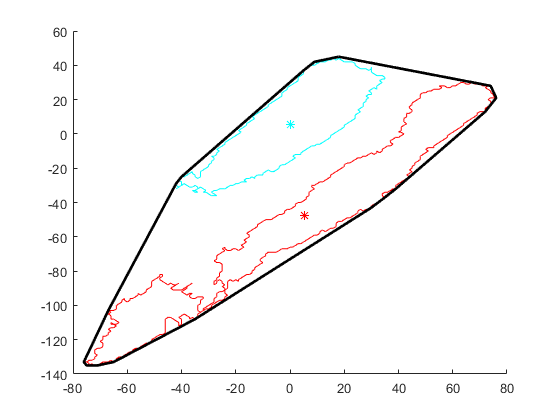

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacko3 = areacKO*(scale)*scale/1000/1000

areacko3 = 0.4103

cko3LHi1 = sqrt((cenHi1cko3x-cenLowcko3x)^2+(cenHi1cko3y-cenLowcko3y)^2)*scale; %meh

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
    hold on
    plot(cko4(x).boundary3(:,2)-cko4(1).centroid(1,1),cko4(x).boundary3(:,1)-cko4(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko4x cenLowcko4y] = centroid(polyshape([cko4(x).boundary3(:,2)-cko4(1).centroid(1,1)],[cko4(x).boundary3(:,1)-cko4(1).centroid(1,2)]));

    plot(cenLowcko4x,cenLowcko4y,'c*')
    boundptsx = [boundptsx,(cko4(1).boundary3(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(1).boundary3(:,1)-cko4(1).centroid(1,2))'];
    plot(cko4(y1).boundary48(:,2)-cko4(1).centroid(1,1),cko4(y1).boundary48(:,1)-cko4(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko4x cenHi1cko4y] = centroid(polyshape([cko4(y1).boundary48(:,2)-cko4(1).centroid(1,1)],[cko4(y1).boundary48(:,1)-cko4(1).centroid(1,2)]));

    plot(cenHi1cko4x,cenHi1cko4y,'r*')
    boundptsx = [boundptsx,(cko4(y1).boundary48(:,2)-cko4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko4(y1).boundary48(:,1)-cko4(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   209
   211
   212
   213
   216
   219
   294
   302
   303


areacKO = 1.0805e+04

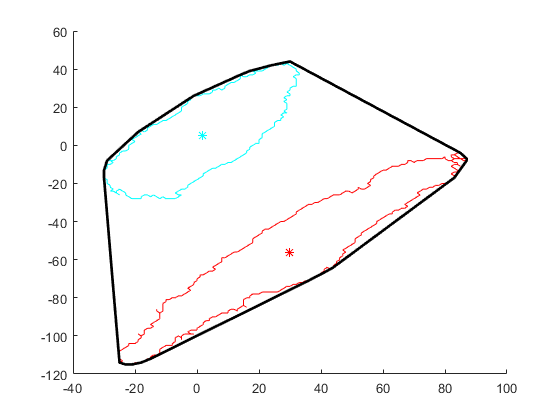

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacko4 = areacKO*(scale)*scale/1000/1000

areacko4 = 0.4131

cko4LHi1 = sqrt((cenHi1cko4x-cenLowcko4x)^2+(cenHi1cko4y-cenLowcko4y)^2)*scale; %meh

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
    hold on
    plot(cko5(x).boundary3(:,2)-cko5(1).centroid(1,1),cko5(x).boundary3(:,1)-cko5(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcko5x cenLowcko5y] = centroid(polyshape([cko5(x).boundary3(:,2)-cko5(1).centroid(1,1)],[cko5(x).boundary3(:,1)-cko5(1).centroid(1,2)]));

    plot(cenLowcko5x,cenLowcko5y,'c*')
    boundptsx = [boundptsx,(cko5(1).boundary3(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(1).boundary3(:,1)-cko5(1).centroid(1,2))'];
    plot(cko5(y1).boundary48(:,2)-cko5(1).centroid(1,1),cko5(y1).boundary48(:,1)-cko5(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1cko5x cenHi1cko5y] = centroid(polyshape([cko5(y1).boundary48(:,2)-cko5(1).centroid(1,1)],[cko5(y1).boundary48(:,1)-cko5(1).centroid(1,2)]));

    plot(cenHi1cko5x,cenHi1cko5y,'r*')
    boundptsx = [boundptsx,(cko5(y1).boundary48(:,2)-cko5(1).centroid(1,1))'];
    boundptsy = [boundptsy,(cko5(y1).boundary48(:,1)-cko5(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   291
   297
   301
   303
   313
   316
   321
   327
   334


areacKO = 1.0504e+04

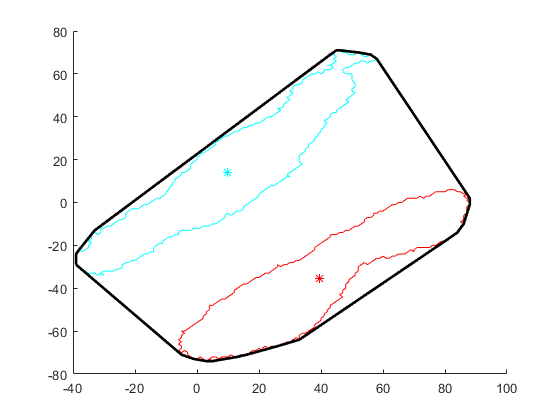

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacko5 = areacKO*(scale)*scale/1000/1000

areacko5 = 0.4016

cko5LHi1 = sqrt((cenHi1cko5x-cenLowcko5x)^2+(cenHi1cko5y-cenLowcko5y)^2)*scale; %meh

EDLHckoall = [cko2LHi1,cko3LHi1,cko4LHi1,cko5LHi1];


% control

scale = 6.1836; % microns per pixel
%con1
figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
    hold on
    plot(con1(x).boundary3(:,2)-con1(1).centroid(1,1),con1(x).boundary3(:,1)-con1(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon1x cenLowcon1y] = centroid(polyshape([con1(x).boundary3(:,2)-con1(1).centroid(1,1)],[con1(x).boundary3(:,1)-con1(1).centroid(1,2)]));

    plot(cenLowcon1x,cenLowcon1y,'c*')
    boundptsx = [boundptsx,(con1(1).boundary3(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(1).boundary3(:,1)-con1(1).centroid(1,2))'];
    plot(con1(y1).boundary48(:,2)-con1(1).centroid(1,1),con1(y1).boundary48(:,1)-con1(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con1x cenHi1con1y] = centroid(polyshape([con1(y1).boundary48(:,2)-con1(1).centroid(1,1)],[con1(y1).boundary48(:,1)-con1(1).centroid(1,2)]));

    plot(cenHi1con1x,cenHi1con1y,'r*')
    boundptsx = [boundptsx,(con1(y1).boundary48(:,2)-con1(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con1(y1).boundary48(:,1)-con1(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   332
   341
   352
   362
   381
   386
   388
   405
   422


areacKO = 8.1205e+03

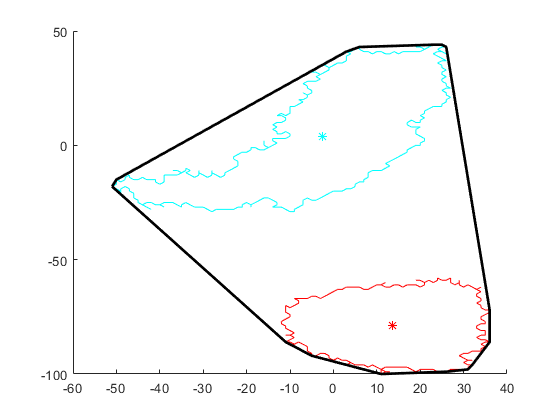

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacon1 = areacKO*(scale)*scale/1000/1000

areacon1 = 0.3105

con1LHi1 = sqrt((cenHi1con1x-cenLowcon1x)^2+(cenHi1con1y-cenLowcon1y)^2)*scale; 

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 1;
    hold on
    plot(con2(x).boundary3(:,2)-con2(1).centroid(1,1),con2(x).boundary3(:,1)-con2(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon2x cenLowcon2y] = centroid(polyshape([con2(x).boundary3(:,2)-con2(1).centroid(1,1)],[con2(x).boundary3(:,1)-con2(1).centroid(1,2)]));

    plot(cenLowcon2x,cenLowcon2y,'c*')
    boundptsx = [boundptsx,(con2(1).boundary3(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(1).boundary3(:,1)-con2(1).centroid(1,2))'];
    plot(con2(y1).boundary48(:,2)-con2(1).centroid(1,1),con2(y1).boundary48(:,1)-con2(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con2x cenHi1con2y] = centroid(polyshape([con2(y1).boundary48(:,2)-con2(1).centroid(1,1)],[con2(y1).boundary48(:,1)-con2(1).centroid(1,2)]));

    plot(cenHi1con2x,cenHi1con2y,'r*')
    boundptsx = [boundptsx,(con2(y1).boundary48(:,2)-con2(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con2(y1).boundary48(:,1)-con2(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   271
   274
   275
   284
   290
   293
   313
   319
   337


areacKO = 1.4418e+04

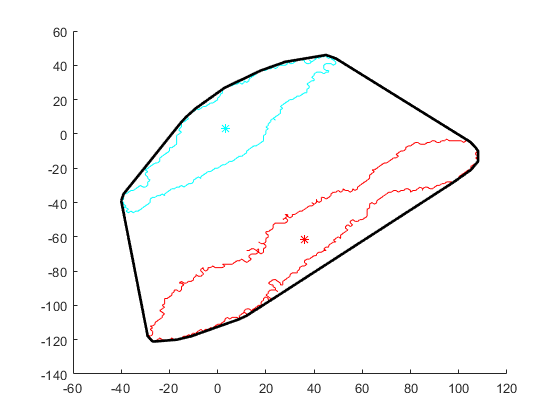

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacon2 = areacKO*(scale)*scale/1000/1000

areacon2 = 0.5513

con2LHi1 = sqrt((cenHi1con2x-cenLowcon2x)^2+(cenHi1con2y-cenLowcon2y)^2)*scale; 

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 2;
    hold on
    plot(con3(x).boundary3(:,2)-con3(1).centroid(1,1),con3(x).boundary3(:,1)-con3(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon3x cenLowcon3y] = centroid(polyshape([con3(x).boundary3(:,2)-con3(1).centroid(1,1)],[con3(x).boundary3(:,1)-con3(1).centroid(1,2)]));

    plot(cenLowcon3x,cenLowcon3y,'c*')
    boundptsx = [boundptsx,(con3(1).boundary3(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(1).boundary3(:,1)-con3(1).centroid(1,2))'];
    plot(con3(y1).boundary48(:,2)-con3(1).centroid(1,1),con3(y1).boundary48(:,1)-con3(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con3x cenHi1con3y] = centroid(polyshape([con3(y1).boundary48(:,2)-con3(1).centroid(1,1)],[con3(y1).boundary48(:,1)-con3(1).centroid(1,2)]));

    plot(cenHi1con3x,cenHi1con3y,'r*')
    boundptsx = [boundptsx,(con3(y1).boundary48(:,2)-con3(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con3(y1).boundary48(:,1)-con3(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
   161
   166
   176
   182
   184
   188
   189
   201
   214


areacKO = 4.6965e+03

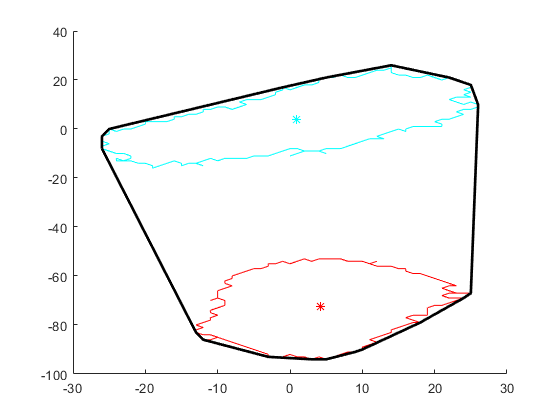

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacon3 = areacKO*(scale)*scale/1000/1000

areacon3 = 0.1796

con3LHi1 = sqrt((cenHi1con3x-cenLowcon3x)^2+(cenHi1con3y-cenLowcon3y)^2)*scale; 

figure;
hold on
boundptsx = [];
boundptsy = [];
x = 1;
y1 = 3;
    hold on
    plot(con4(x).boundary3(:,2)-con4(1).centroid(1,1),con4(x).boundary3(:,1)-con4(1).centroid(1,2),'c','LineWidth', 1)
    [cenLowcon4x cenLowcon4y] = centroid(polyshape([con4(x).boundary3(:,2)-con4(1).centroid(1,1)],[con4(x).boundary3(:,1)-con4(1).centroid(1,2)]));

    plot(cenLowcon4x,cenLowcon4y,'c*')
    boundptsx = [boundptsx,(con4(1).boundary3(:,2)-con4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con4(1).boundary3(:,1)-con4(1).centroid(1,2))'];
    plot(con4(y1).boundary48(:,2)-con4(1).centroid(1,1),con4(y1).boundary48(:,1)-con4(1).centroid(1,2),'r','LineWidth', 1)
    [cenHi1con4x cenHi1con4y] = centroid(polyshape([con4(y1).boundary48(:,2)-con4(1).centroid(1,1)],[con4(y1).boundary48(:,1)-con4(1).centroid(1,2)]));

    plot(cenHi1con4x,cenHi1con4y,'r*')
    boundptsx = [boundptsx,(con4(y1).boundary48(:,2)-con4(1).centroid(1,1))'];
    boundptsy = [boundptsy,(con4(y1).boundary48(:,1)-con4(1).centroid(1,2))'];
    [k areacKO] = boundary(boundptsx',boundptsy',0)

k =      1
     6
    10
   510
   520
   531
   534
   535
   541
   548


areacKO = 11256

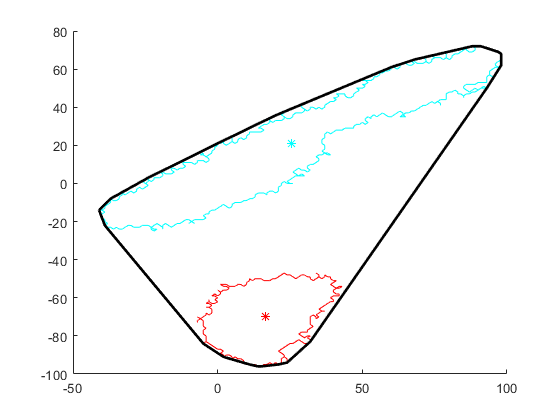

plot(boundptsx(k),boundptsy(k),'k','LineWidth',2)

areacon4 = areacKO*(scale)*scale/1000/1000

areacon4 = 0.4304

con4LHi1 = sqrt((cenHi1con4x-cenLowcon4x)^2+(cenHi1con4y-cenLowcon4y)^2)*scale; 

EDLHconall = ([con1LHi1,con2LHi1,con3LHi1,con4LHi1]);

figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Low high1 dist (um)';
dim1 = [1 2];
[fig1 h p1] = compare2(EDLHconall,EDLHckoall,conditions1,ylbl1,dim1)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 174
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p1 = 0.0286

p1

p1 = 0.0286

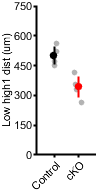

ylim([0 750])
yticks([0 150 300 450 600 750])

subP = handleTheSubplot({fig1,fig1,fig1},[1 3]);

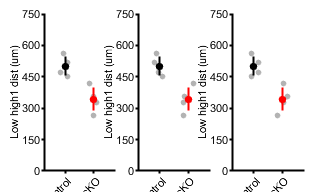

figQuality(subP,gca,[3 2])